clear;
clc;

## Scenario Setup

Describe physical parameters (Load from Base Scenario file)

ScenarioBase();

## Execute Scenario

Prepare Sim: Assume Fixed Delay and Bandwidth per iteration; no relays, no bandwidth variance

TDelayAtStep = DelayPhysDist;
BRPerStep = BRMax * TimeStep; % Naive way to get bit-rate into "boxes" of a certain data size

Generate Items (command sent at $t=0$ so sim starts after delay)

ItemList(1) = Item("Photo", 0,  3, 6 * TimeStep, TimeStep * 10);
ItemList(2) = Item("Video", 0,  9, 12 * TimeStep, TimeStep * 2);
ItemList(3) = Item("Loc",   0, 10, 1 * TimeStep, TimeStep);
ItemList(4) = Item("Stats", 0,  5, 3 * TimeStep, TimeStep * 5);
ItemList(5) = Item("LIDAR", 0,  9, 8 * TimeStep, TimeStep * 2);

for i=6:MaxItems
    ItemList(i) = Item(i, 0, rand()*10,  (BRMax * rand()/2) * TimeStep, TimeStep * rand() * 10);
end

ItemCount = numel(ItemList);

At $t=T_d$ we received a command on the Moon, updates will now start sending from Moon to Earth

% First-Update-First-Serve (First-Update) Method
SendSimple();
% Max(AoI) Method
SendMaxAoI();
% MAB Method
SendMAB();

Plot The Data

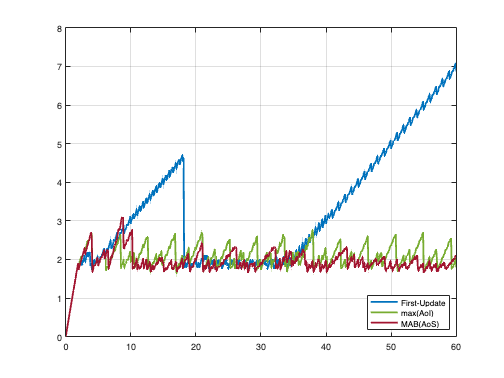

figure(1);
hold on;
grid on;
box on;
plot(LoggedXTime,LoggedYAoSSimple, '-', Color="#0072BD", LineWidth=2);
plot(LoggedXTime,LoggedYAoSMaxAoI, '-', Color="#77AC30", LineWidth=2);
plot(LoggedXTime,LoggedYAoSMAB, '-', Color="#A2142F", LineWidth=2);
pltLabels = ["First-Update", "max(AoI)", "MAB(AoS)"];
% for i=1:ItemCount
%     plot(LoggedXTime, LoggedAoSItemSimple(i,:), ':', LineWidth=0.5);
%     pltLabels = [pltLabels ("I=" + string(i))];
% end
legend(pltLabels,"Location","southeast");
hold off;

% Show some real data being moved around in a graph, to be able to show 
% updates missed that would result in instability

% Add 3d graph for more items at fixed - 


Graph Data

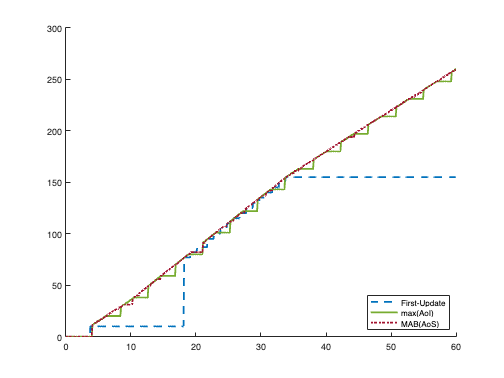

figure(2);
clf;
hold on;
itemOfInterest = 5;
plot(LoggedXTime,LoggedDataSimple(:, itemOfInterest), '--', Color="#0072BD", LineWidth=2);
plot(LoggedXTime,LoggedDataMaxAoI(:, itemOfInterest), '-', Color="#77AC30", LineWidth=2);
plot(LoggedXTime,LoggedDataMAB(:, itemOfInterest), ':', Color="#A2142F", LineWidth=2);
legend(pltLabels,"Location","southeast");
hold off;

Graph Send Count Averages

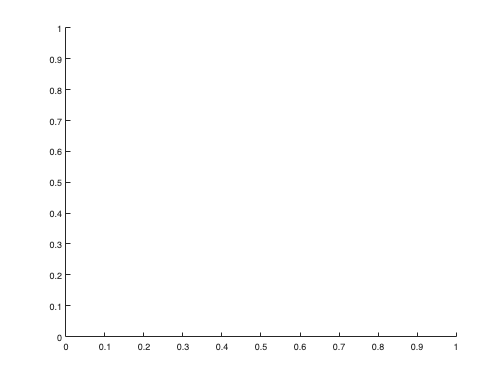

figure(3);
clf;
hold on;